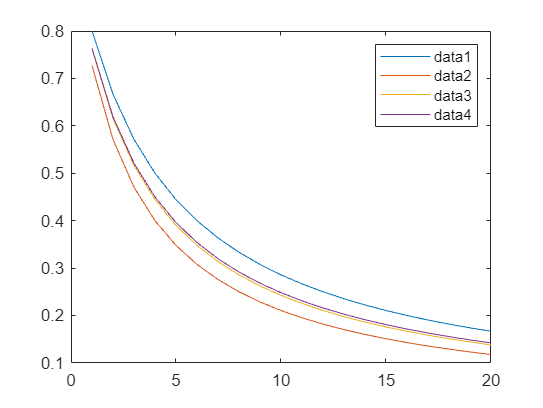

clear all
Vimax = 18;
Vimin = 12;

N = linspace(1,20,20);

Dmax_vec = zeros(1,20);
Dmin_vec = zeros(1,20);

Vo = 48;

for i=1:20
    d1 = ((1/N(i)) * (Vo/Vimin))./(1+(1/N(i)) * (Vo/Vimin));
    d2 = ((1/N(i)) * (Vo/Vimax))./(1+(1/N(i)) * (Vo/Vimax));
    dmax = max(d1,d2);
    dmin = min(d1,d2);
    Dmax_vec(i) = dmax;
    Dmin_vec(i) = dmin;
end

plot(N,Dmax_vec);
hold on
plot(N,Dmin_vec);
hold on
legend
hold off

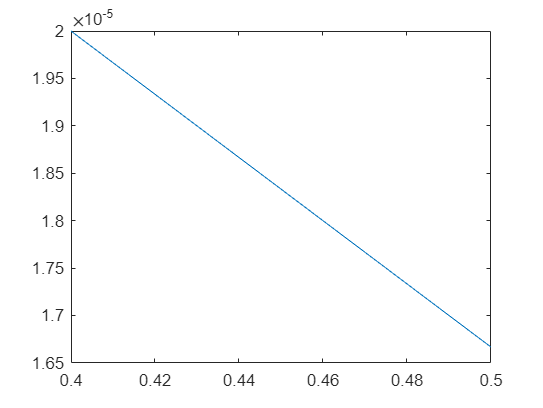

%%%
N = 4; % N2/N1
fs = 2e5;
delta_ilm = 1.8;
duty_cycle_vec = linspace(0.40, 0.50, 50);
Lmvec = zeros(1,50);

for i=1:50
    Lmvec(i)=(Vo*(1-duty_cycle_vec(i)) * 0.25 )/(fs*delta_ilm);
end

plot(duty_cycle_vec, Lmvec)


%%%

Acore =  60e-6;
rel = 0.0053;
mu0 = 4*pi*1e-7;
gap = rel*Acore*mu0

gap = 3.9961e-13